# **PESTools - Example 006 - Testing the file loaders**

This example shows how to perform common operations on ARPES data using the functions of the MATools and PESTools toolkit.

For a more in-depth explanation of potential in- and output of those functions, consult the UserGuide.

close all; clear all;
pp          = plot_props();
path_data   = 'D:\OneDrive\PCC_MS_Project\00_SLS_Software\ADRESSTools\ADRESSTools_vEos\PESTools_PCC\Examples\Example_Data\';

# **(1) Creating artificial data structures**

temp_arpes_data = create_arpes_data()
temp_pes_data   = create_pes_data()

# **(2.1) SIS Beamline, ULTRA: **Testing Eb(kx) data processing

**(A) Loading in the ARPES data files**

% Loading in the data files
file_names      = {...
    'SIS_GXCut_59_Cp_0000.h5',...
    };
arpes_dat = cell(1,length(file_names));
for i = 1:length(file_names); arpes_dat{i} = load_sis_data(file_names{i}, path_data); end
view_arpes_data(arpes_dat{1});
% Cross-correlating the data files
for i = 1:length(arpes_dat); arpes_dat{i} = xcorr_scans(arpes_dat{i}); end
view_arpes_data(arpes_dat{1});

**(B) Loading in the Fermi-Edge reference files**

% Loading in the data files
file_names_ef      = {...
    'SIS_Au_59eV_0000.h5',...
    };
arpes_ref = cell(1,length(file_names_ef));
for i = 1:length(file_names_ef); arpes_ref{i} = load_sis_data(file_names_ef{i}, path_data); end
view_arpes_data(arpes_ref{1});
% Cross-correlating the reference files to get a good estimate on EF
for i = 1:length(arpes_ref); arpes_ref{i} = xcorr_scans(arpes_ref{i}); end
view_arpes_data(arpes_ref{1});

**(C) Binding energy alignment to the reference data**

% (1) COARSE ALIGNMENT TO THE EDGE
% -- Coarse alignment of the energy
alignType   = "align2ref";      % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];               % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = 0.0;              % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 4.00;             % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];               % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';           % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(arpes_dat)
    [arpes_dat{i}, arpes_ref{i}]  = align_energy(arpes_dat{i}, align_args, arpes_ref{i});
end
view_arpes_data(arpes_ref{1}); line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 
% (2) FITTING TO THE FDD WITH FINE ALIGNMENT
alignType   = "fit2ef";        % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];              % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = 0.00;            % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 0.50;            % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];              % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';          % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(arpes_dat)
    arpes_dat{i}  = align_energy(arpes_dat{i}, align_args, arpes_ref{i}); 
end
view_arpes_data(arpes_dat{1});
line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--');

**(D) Background subtraction and intensity normalisation**

bgrdType    = "AngleInt-clip";   % either "angle/kx-int (fixed edc)", "angle/kx-int (fixed edc) (per channel)", "angle/kx-int (fixed mean)", "angle/kx-int (moving mean)", "none"
bgrdWin     = [];                  % EDC angle range to integrate over to extract ISubtr
bgrdScale   = 0.25;                         % scale coefficient to subtract (Data - intScale * ISubtr)
bgrdSmooth  = 25;                          % single, constant value that determine presmoothing of data to extract background. 
normType    = "max-each";           % "max (all scans)", "max (each scan)", "mean (each scan)", "none"
bgrd_args   = {bgrdType, bgrdWin, bgrdScale, bgrdSmooth, normType}; 
for i = 1:length(arpes_dat)
    arpes_dat{i} = bgrd_subtr_data(arpes_dat{i}, bgrd_args); 
end
view_arpes_data(arpes_dat{1});

**(E) Wave-vector conversions**

eB_ref      = 0;            % single, constant value of the binding energy at the refernece point.
kx_ref      = 0;            % single, constant value of the wave-vector value at the reference point.
thtA_ref    = 3.798;         % single, constant value of the tht angle value at the reference point.
v000        = 12.57;        % single, constant value of the inner potential. Tune to make sure spacing of Gamma points is correct. Default is 12.57.
kconv_args  = {eB_ref, kx_ref, thtA_ref, v000}; 
for i = 1:length(arpes_dat)
    arpes_dat{i} = convert_to_k(arpes_dat{i}, kconv_args);
    % -- custom shift to centralise kx
    arpes_dat{i}.kx = arpes_dat{i}.kx;
end
view_arpes_data(arpes_dat{1});

**(F) Cropping the ARPES data**

xLims       = [-0.55, 0.55];    % x-axis limits to crop (if empty like [], does not crop this axis)
yLims       = [-2.25, 0.25];     % y-axis limits to crop (if empty like [], does not crop this axis)
zLims       = [];               % z-axis limits to crop (if empty like [], does not crop this axis)
for i = 1:length(arpes_dat) 
    arpes_dat{i} = data_crop3D(arpes_dat{i}, xLims, yLims, zLims);
    view_arpes_data(arpes_dat{i}); arpes_dat{i}
end

**(G) Extracting a series of EDC cuts**

nFrame          = 1;                    % Scan number to be cut
isocutType          = "EDC";            % Type of line profile to extract. "EDC" (vertical) or "MDC" (horizontal)
isocutWin           = 0.02;             % single, constant valueof the integration window.
isocutXLims         = [-0.45, 0.45];    % 1x2 vector which gives the x-axis limits of the train [minX, maxX]
isocutYLims         = [-2.1, 0.1];      % 1x2 vector which gives the y-axis limits of the train [minY, maxY]
isocutN             = 25;               % single, constant value that determines the total number of line profiles to extract
isocut_args         = {nFrame, isocutType, isocutWin, isocutXLims, isocutYLims, isocutN};
plot_result         = 1;                % Show a plot of the data that is extracted. if 1, it will make the plot, if 0 it won't.
[cutStr_03, ~]      = extract_isoCut_series(arpes_dat{1}, isocut_args, plot_result); cutStr_03

# **(2.2) SIS Beamline, ULTRA:** Testing PES Data Processing

**(A) Loading in the PES data files**

% Explicitely defining the file-names
file_names      = {...
    'SIS_XPS_750eV_0000.h5',...
    };
% Load in the data
PES_dat = cell(1,length(file_names));
for i = 1:length(file_names); PES_dat{i} = load_sis_data(file_names{i}, path_data); end
view_arpes_data(PES_dat{1}); PES_dat{1}

**(B) Loading in the Fermi edge reference via gold / copper**

% Explicitely defining the file-names
file_names_ef      = {...
    'SIS_Au_750eV_0000.h5',...
    };
% Load in the data
PES_ref = cell(1,length(file_names_ef));
for i = 1:length(file_names_ef); PES_ref{i} = load_sis_data(file_names_ef{i}, path_data); end
view_arpes_data(PES_ref{1}); PES_ref{1}

**(C) Binding energy alignment to the reference data**

% (1) AUTOMATIC COARSE ALIGNMENT TO THE EDGE OF THE REFERENCE
% -- Coarse alignment of the energy
alignType   = "align2ref";        % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];               % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = 0.00;                % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 4.00;              % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];               % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';           % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(PES_dat)
    PES_dat{i}  = align_energy(PES_dat{i}, align_args, PES_ref{i}); 
    PES_ref{i}.raw_eb = PES_ref{i}.raw_eb - PES_dat{i}.eb_shifts{1};
    view_arpes_data(PES_ref{i});
    line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 
end
% (2) FITTING TO THE FDD WITH FINE ALIGNMENT
alignType   = "fit2ef-75%";        % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];               % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = -0.5;                % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 3.0;              % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];               % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';           % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(PES_dat)
    PES_dat{i}  = align_energy(PES_dat{i}, align_args, PES_ref{i}, 1); 
end
view_arpes_data(PES_dat{1});
line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 

**(D) Extract the PES data by angle-integrating the ARPES spectrum**

cutWin          = 0.95*[min(PES_dat{1}.tht(:)), max(PES_dat{1}.tht(:))];    % Integration window of the cut to be made.
cutN            = 1;                                                        % Single, constant value that determines the total number of line profiles to extract
xps_args        = {cutWin, cutN};
for i = 1:length(PES_dat)
    [PES_dat{i}, ~]     = pes_extract_data(PES_dat{i}, xps_args);
end
if length(PES_dat{i}) > 1; PES_dat = [PES_dat{:}]; end
view_arpes_data(PES_dat{1});

**(E) Normalisation of the PES spectrum**

eWin            = -444;        % approximate Eb position of a peak in the spectrum to normalise to.
dEWin           = 5;          % can be empty []. Single, constant value that defines the width of the approximate Eb position
norm_args    = {eWin, dEWin};
for i = 1:length(PES_dat)
    PES_dat{i}.ydat = pes_norm2peak(PES_dat{i}.xdat, PES_dat{i}.ydat, norm_args, 1);
end
view_pes_data(PES_dat{1});

**(F) Final data structure after all the processing**

view_pes_data(PES_dat); PES_dat{1}
lgnd = {}; for i = 1:length(PES_dat); lgnd{end+1} = string(PES_dat{i}.hv) + " eV"; end
legend(lgnd,'Location','best'); title(sprintf("XPS Survey at SIS"), 'interpreter', 'none');

# **(3.1) PEARL Beamline: **Testing data loader

close all; clear all;
path_data   = 'D:\OneDrive\PCC_MS_Project\00_SLS_Software\ADRESSTools\ADRESSTools_vEos\PESTools_PCC\Examples\Example_Data\';

**(A) Manipulator Scan**

dataStr = load_pearl_data('PEARL_ManipulatorScan.h5', path_data); 

Loading PEARL data...


dataStr


dataStr =

  0×0 empty cell array



**(B) MultiRegionScan**

file_names = 'PEARL_MultiRegionScan2022.h5';
xps_raw = load_pearl_data(file_names, path_data);

Loading PEARL data...


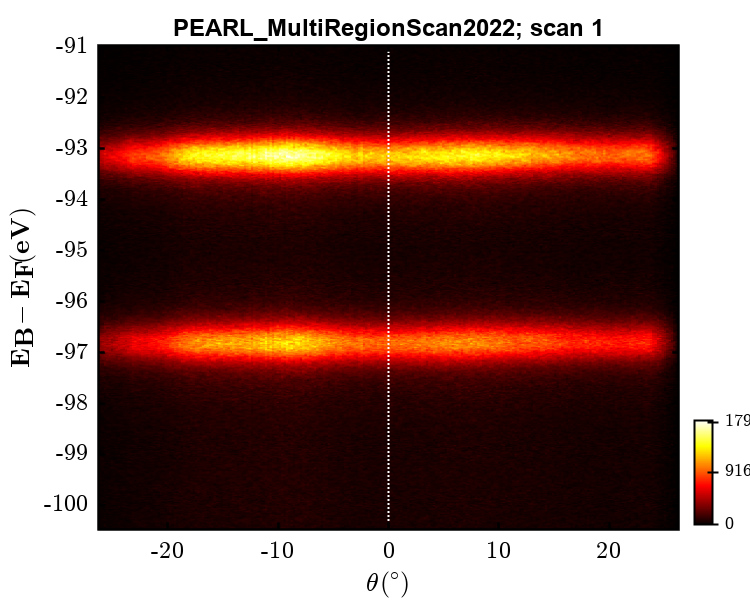

ans = struct with fields:
     FileName: 'PEARL_MultiRegionScan2022'
       H5file: 'PEARL_MultiRegionScan2022.h5'
    TimeStamp: "07-Oct-2022 00:49:18"
         Type: "Eb(k)"
        index: 1
         meta: [1×1 struct]
           hv: 1.0500e+03
         phiM: [2×1 double]
         thtM: [2×1 double]
         tltM: [2×1 double]
         Temp: 19.7610
     raw_data: [476×250 double]
      raw_tht: [-26.3360 -26.1245 -25.9129 -25.7014 -25.4899 -25.2783 -25.0668 -24.8553 -24.6437 -24.4322 -24.2207 -24.0091 -23.7976 -23.5861 -23.3745 -23.1630 -22.9515 -22.7399 -22.5284 -22.3169 -22.1053 -21.8938 -21.6822 -21.4707 -21.2592 -21.0476 … ]
       raw_eb: [476×1 double]


%% (1.1) - Load in data
% Load in XPS data
xps_dat = xps_raw{1}; xps_dat = xfrag_scans(xps_dat); view_arpes_data(xps_dat{1}); xps_dat{1}

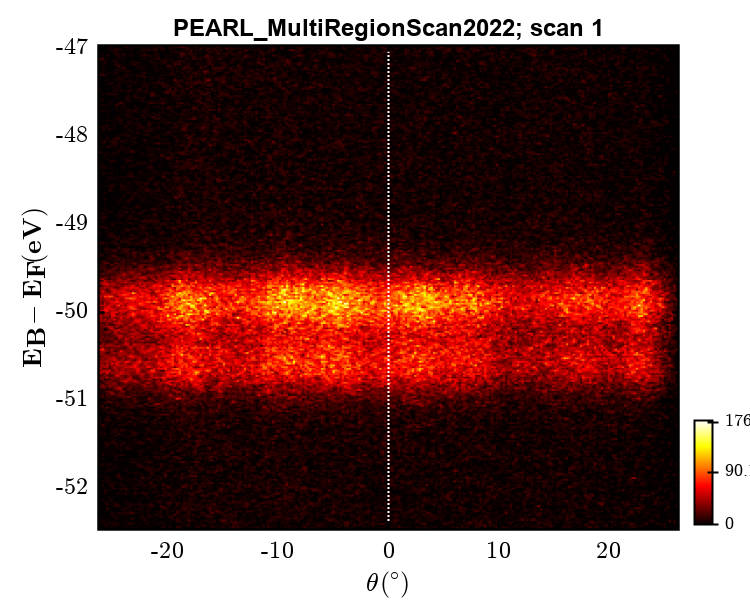

ans = struct with fields:
     FileName: 'PEARL_MultiRegionScan2022'
       H5file: 'PEARL_MultiRegionScan2022.h5'
    TimeStamp: "07-Oct-2022 00:49:18"
         Type: "Eb(k)"
        index: 1
         meta: [1×1 struct]
           hv: 1.0500e+03
         phiM: -90
         thtM: -9
         tltM: -2
         Temp: 19.7610
     raw_data: [276×250 double]
      raw_tht: [-26.3360 -26.1245 -25.9129 -25.7014 -25.4899 -25.2783 -25.0668 -24.8553 -24.6437 -24.4322 -24.2207 -24.0091 -23.7976 -23.5861 -23.3745 -23.1630 -22.9515 -22.7399 -22.5284 -22.3169 -22.1053 -21.8938 -21.6822 -21.4707 -21.2592 -21.0476 … ]
       raw_eb: [276×1 double]


xps_dat = xps_raw{2}; xps_dat = xfrag_scans(xps_dat); view_arpes_data(xps_dat{1}); xps_dat{1}

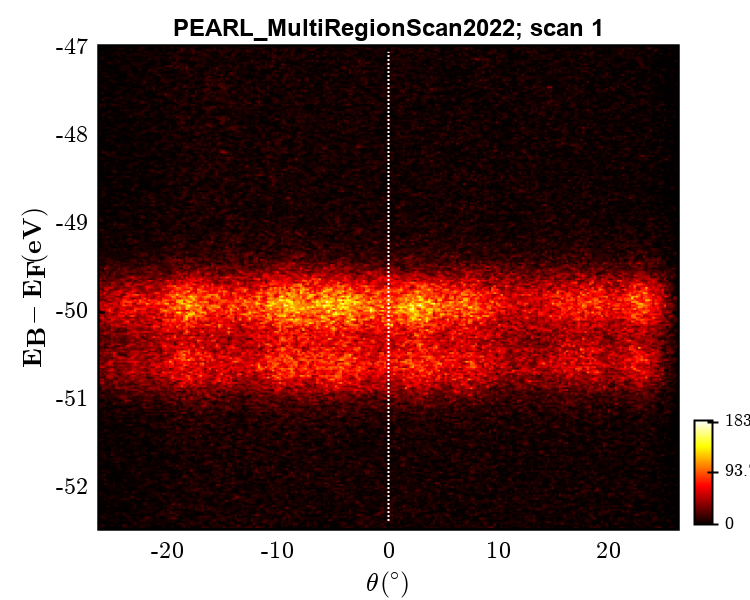

ans = struct with fields:
     FileName: 'PEARL_MultiRegionScan2022'
       H5file: 'PEARL_MultiRegionScan2022.h5'
    TimeStamp: "07-Oct-2022 00:49:18"
         Type: "Eb(k)"
        index: 1
         meta: [1×1 struct]
           hv: 1.0500e+03
         phiM: -90
         thtM: -9
         tltM: -2
         Temp: 19.7610
     raw_data: [276×250 double]
      raw_tht: [-26.3360 -26.1245 -25.9129 -25.7014 -25.4899 -25.2783 -25.0668 -24.8553 -24.6437 -24.4322 -24.2207 -24.0091 -23.7976 -23.5861 -23.3745 -23.1630 -22.9515 -22.7399 -22.5284 -22.3169 -22.1053 -21.8938 -21.6822 -21.4707 -21.2592 -21.0476 … ]
       raw_eb: [276×1 double]


xps_dat = xps_raw{3}; xps_dat = xfrag_scans(xps_dat); view_arpes_data(xps_dat{1}); xps_dat{1}

ans = struct with fields:
     FileName: 'PEARL_MultiRegionScan2022'
       H5file: 'PEARL_MultiRegionScan2022.h5'
    TimeStamp: "07-Oct-2022 00:49:18"
         Type: "Eb(k)"
        index: 1
         meta: [1×1 struct]
           hv: 1.0500e+03
         phiM: [2×1 double]
         thtM: [2×1 double]
         tltM: [2×1 double]
         Temp: 19.7610
     raw_data: [476×250 double]
      raw_tht: [-26.3360 -26.1245 -25.9129 -25.7014 -25.4899 -25.2783 -25.0668 -24.8553 -24.6437 -24.4322 -24.2207 -24.0091 -23.7976 -23.5861 -23.3745 -23.1630 -22.9515 -22.7399 -22.5284 -22.3169 -22.1053 -21.8938 -21.6822 -21.4707 -21.2592 -21.0476 … ]
       raw_eb: [476×1 double]


% Load in XPS reference data
xps_ref = xps_raw{1}; xps_ref = xfrag_scans(xps_ref);  view_arpes_data(xps_ref{1}); xps_ref{1}

**(C) MultiRegionScan - different photon energies**

file_names = 'PEARL_MultiRegionScan_HvChanging.h5';
xps_raw = load_pearl_data(file_names, path_data); xps_raw{1}

Loading PEARL data...


initStr = struct with fields:
    general: [1×1 struct]
       logs: [1×1 struct]
     scan_1: [1×1 struct]


ans = struct with fields:
            PositionPhi: -90
          PositionTheta: -9
           PositionTilt: -2
              PositionX: 3.4500
              PositionY: 3
              PositionZ: 113.5000
             RefCurrent: 1.4613e-09
          SampleCurrent: 1.9673e-10
    ScientaChannelBegin: 300
      ScientaChannelEnd: 1050
           ScientaImage: [1×3751×250 double]
      ScientaIterations: 1
      ScientaPassEnergy: 50
        ScientaSpectrum: [3751×1 double]
      ScientaStepEnergy: 0.2000
        ScientaStepTime: 0.1000


ans = 3.4499

ans = struct with fields:
     FileName: 'PEARL_MultiRegionScan_HvChanging'
       H5file: 'PEARL_MultiRegionScan_HvChanging.h5'
    TimeStamp: "07-Apr-2023 12:09:26"
         Type: "Eb(k)"
        index: 1
         meta: [1×1 struct]
           hv: 1.0500e+03
         phiM: [2×1 double]
         thtM: [2×1 double]
         tltM: [2×1 double]
         Temp: 23.2780
     raw_data: [151×250 double]
      raw_tht: [-26.3360 -26.1245 -25.9129 -25.7014 -25.4899 -25.2783 -25.0668 -24.8553 -24.6437 -24.4322 -24.2207 -24.0091 -23.7976 -23.5861 -23.3745 -23.1630 -22.9515 -22.7399 -22.5284 -22.3169 -22.1053 -21.8938 -21.6822 -21.4707 -21.2592 -21.0476 … ]
       raw_eb: [151×1 double]


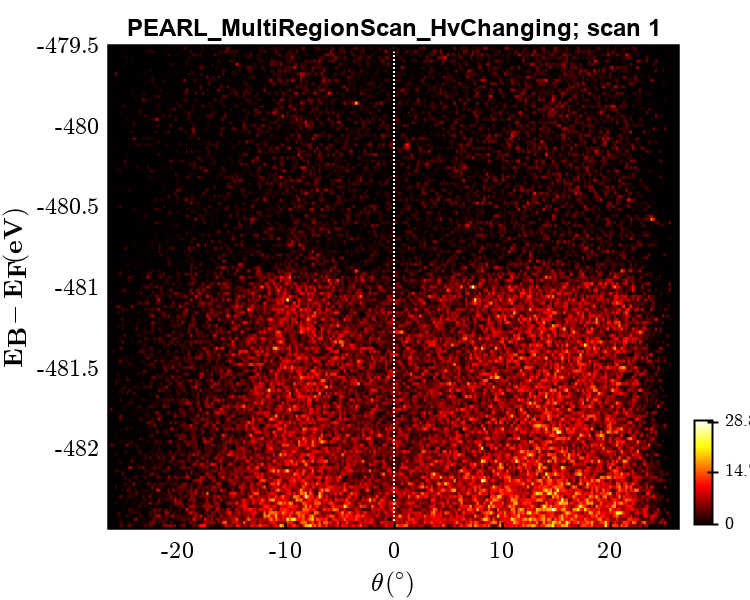

ans = struct with fields:
     FileName: 'PEARL_MultiRegionScan_HvChanging'
       H5file: 'PEARL_MultiRegionScan_HvChanging.h5'
    TimeStamp: "07-Apr-2023 12:09:26"
         Type: "Eb(k)"
        index: 1
         meta: [1×1 struct]
           hv: 1.0500e+03
         phiM: [2×1 double]
         thtM: [2×1 double]
         tltM: [2×1 double]
         Temp: 23.2780
     raw_data: [151×250 double]
      raw_tht: [-26.3360 -26.1245 -25.9129 -25.7014 -25.4899 -25.2783 -25.0668 -24.8553 -24.6437 -24.4322 -24.2207 -24.0091 -23.7976 -23.5861 -23.3745 -23.1630 -22.9515 -22.7399 -22.5284 -22.3169 -22.1053 -21.8938 -21.6822 -21.4707 -21.2592 -21.0476 … ]
       raw_eb: [151×1 double]


%% (1.1) - Load in data
% -- 578 eV data (must manually define hv)
xps_dat01 = xps_raw{1}; xps_dat01 = xfrag_scans(xps_dat01); view_arpes_data(xps_dat01{1}); xps_dat01{1}

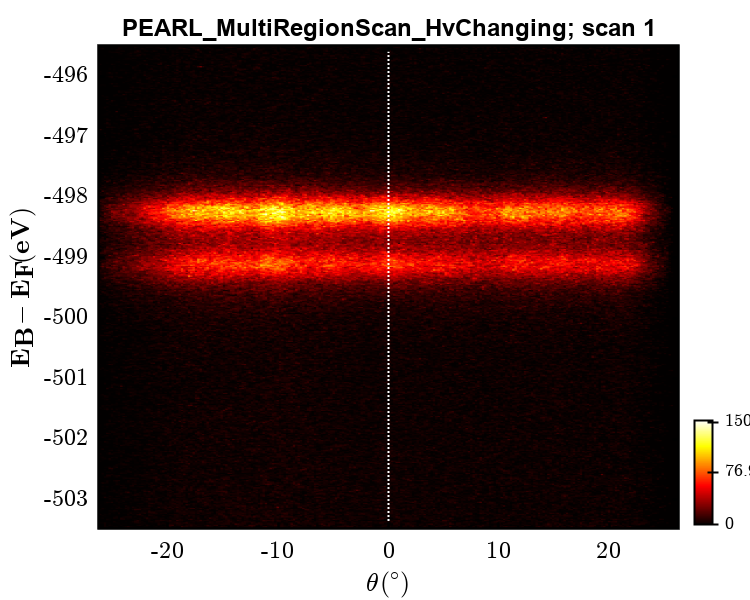

ans = struct with fields:
     FileName: 'PEARL_MultiRegionScan_HvChanging'
       H5file: 'PEARL_MultiRegionScan_HvChanging.h5'
    TimeStamp: "07-Apr-2023 12:09:26"
         Type: "Eb(k)"
        index: 1
         meta: [1×1 struct]
           hv: 1.0500e+03
         phiM: -90
         thtM: -9
         tltM: -2
         Temp: 23.2780
     raw_data: [401×250 double]
      raw_tht: [-26.3360 -26.1245 -25.9129 -25.7014 -25.4899 -25.2783 -25.0668 -24.8553 -24.6437 -24.4322 -24.2207 -24.0091 -23.7976 -23.5861 -23.3745 -23.1630 -22.9515 -22.7399 -22.5284 -22.3169 -22.1053 -21.8938 -21.6822 -21.4707 -21.2592 -21.0476 … ]
       raw_eb: [401×1 double]


xps_dat02 = xps_raw{2}; xps_dat02 = xfrag_scans(xps_dat02); view_arpes_data(xps_dat02{1}); xps_dat02{1}

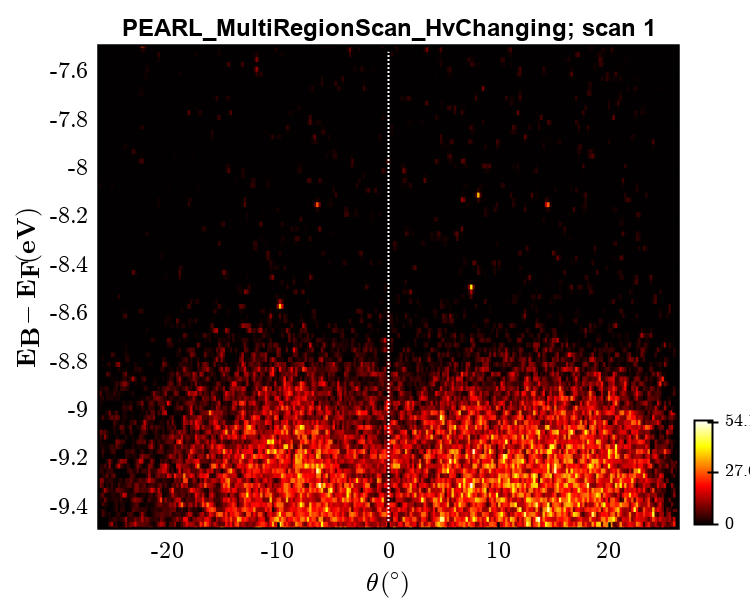

ans = struct with fields:
     FileName: 'PEARL_MultiRegionScan_HvChanging'
       H5file: 'PEARL_MultiRegionScan_HvChanging.h5'
    TimeStamp: "07-Apr-2023 12:09:26"
         Type: "Eb(k)"
        index: 1
         meta: [1×1 struct]
           hv: 1.0500e+03
         phiM: -90
         thtM: -9
         tltM: -2
         Temp: 23.2780
     raw_data: [101×250 double]
      raw_tht: [-26.3360 -26.1245 -25.9129 -25.7014 -25.4899 -25.2783 -25.0668 -24.8553 -24.6437 -24.4322 -24.2207 -24.0091 -23.7976 -23.5861 -23.3745 -23.1630 -22.9515 -22.7399 -22.5284 -22.3169 -22.1053 -21.8938 -21.6822 -21.4707 -21.2592 -21.0476 … ]
       raw_eb: [101×1 double]


% -- 1050 eV data
xps_dat09 = xps_raw{9}; xps_dat09 = xfrag_scans(xps_dat09); view_arpes_data(xps_dat09{1}); xps_dat09{1}

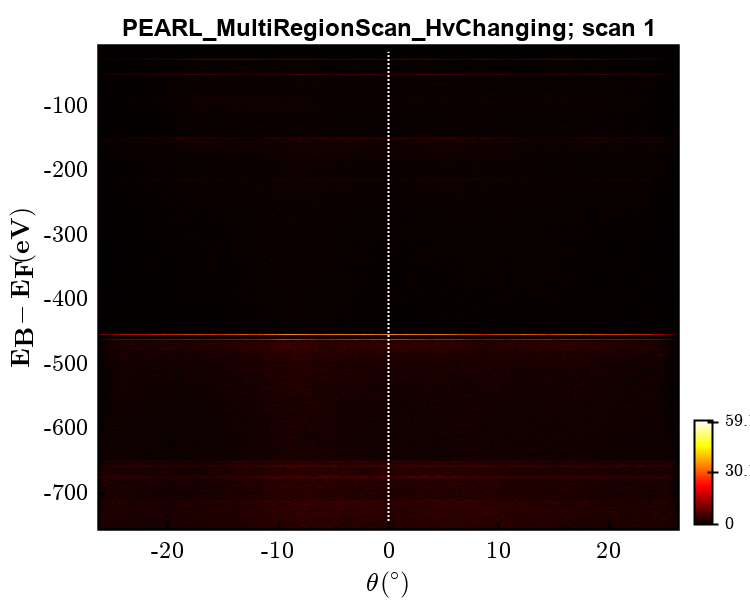

ans = struct with fields:
     FileName: 'PEARL_MultiRegionScan_HvChanging'
       H5file: 'PEARL_MultiRegionScan_HvChanging.h5'
    TimeStamp: "07-Apr-2023 12:09:26"
         Type: "Eb(k)"
        index: 1
         meta: [1×1 struct]
           hv: 1.0500e+03
         phiM: -90
         thtM: -9
         tltM: -2
         Temp: 23.2780
     raw_data: [3751×250 double]
      raw_tht: [-26.3360 -26.1245 -25.9129 -25.7014 -25.4899 -25.2783 -25.0668 -24.8553 -24.6437 -24.4322 -24.2207 -24.0091 -23.7976 -23.5861 -23.3745 -23.1630 -22.9515 -22.7399 -22.5284 -22.3169 -22.1053 -21.8938 -21.6822 -21.4707 -21.2592 -21.0476 … ]
       raw_eb: [3751×1 double]


xps_dat10 = xps_raw{10}; xps_dat10 = xfrag_scans(xps_dat10); view_arpes_data(xps_dat10{1}); xps_dat10{1}

**(D) Photon Energy Dependence**

file_names = 'PEARL_PhotonEnergy.h5';
xps_raw = load_pearl_data(file_names, path_data); 

Loading PEARL data...


ans = struct with fields:
                        Eph: [11×1 double]
     ImageAngleDistribution: [250×11 double]
                ImageCounts: [11×1 double]
    ImageEnergyDistribution: [451×11 double]
             MachineCurrent: [11×1 double]
                 RefCurrent: [11×1 double]
              SampleCurrent: [11×1 double]
          ScientaHighEnergy: [11×1 double]
               ScientaImage: [11×451×250 double]
           ScientaLowEnergy: [11×1 double]
            ScientaSpectrum: [451×11 double]
                      attrs: [1×1 struct]
                       meta: [1×1 struct]


xps_raw

xps_raw = struct with fields:
     FileName: 'PEARL_PhotonEnergy'
       H5file: 'PEARL_PhotonEnergy.h5'
    TimeStamp: "07-Apr-2023 12:09:31"
         Type: "Eb(k,hv)"
        index: [1 2 3 4 5 6 7 8 9 10 11]
         meta: [1×1 struct]
           hv: [11×1 double]
         phiM: [11×1 double]
         thtM: [11×1 double]
         tltM: [11×1 double]
         Temp: 22.0452
     raw_data: [451×250×11 double]
      raw_tht: [-26.3360 -26.1245 -25.9129 -25.7014 -25.4899 -25.2783 -25.0668 -24.8553 -24.6437 -24.4322 -24.2207 -24.0091 -23.7976 -23.5861 -23.3745 -23.1630 -22.9515 -22.7399 -22.5284 -22.3169 -22.1053 -21.8938 -21.6822 -21.4707 -21.2592 -21.0476 … ]
       raw_eb: [351×11 double]
